# EE105 Simulink Lab: Numeric Simulation

# Name: Buddy Ugwumba SID: 86203029

Objective

- The objective of this lab is to understand the process and pitfalls of the numeric solution of differential equations. 

- In this lab we will learn how to simulate a dynamic system on a computer and will construct such a simulation. Vector and matrix notion must be used throughout this lab

Background

- The numeric solution of a differential equation is referred to as **simulation**. 

- SImulation can be used both to verify the accuracy of my model and to experiment with the performance of my system 

- For all but the simplest systems, a numeric solution is much easier than an analytical one

- In this lab we will use the following equations to simulate the performance of a simple system where k = 1, 2, 3......


$$\begin{array}{l}
{\mathit{\mathbf{x}}}_{k+1} \approx {\mathit{\mathbf{x}}}_k +f\left({\mathit{\mathbf{x}}}_k ,u_k \right)*h\;\;\left(4\right)\\
y_k =g\left({\mathit{\mathbf{x}}}_{\left.k\right)} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\right)
\end{array}$$


- Each iteration of these equations advances the solution by h seconds.

- Sinulation from $t_0$ to $t_f$ will require $N=\frac{t_f -t_0 }{h}$ iterations 

- *h* cannot be larger than the time constant because the system would oscillate.

- A good rule of thumb is to select the step-size h to yield at least ten samples for the fastest time constant. (i.e. time constatn 

Prelab

- The standard form for the transfer function of a low pass second order system is:


$$H\left(s\right)=\frac{Gw_n^2 }{s^2 +2{\zeta \omega }_n s+\omega_n^2 }$$


where s is the Laplace variable, G is the DC gain, $\omega_n$ is the undamped natural frequency, and $\zeta$ is the damping factor.

- Two additionally important parameters are the decay rate $\sigma =\zeta w_n$ and the undamped natural frequency $\omega_d =\omega_n \sqrt{1-\zeta }$

- For the transfer function in eqn. (6), whare the values of G, $\zeta ,\omega_n ,\sigma ,\mathrm{and}\;\omega_d$

                G = 1 $\omega_n$ = 4, $\zeta =\frac{3}{4}$, $\sigma =3$ and $\omega_d =2$

        2. Use the ideas from frequency response, i.e.


$$Y\left(s\right)=H\left(s\right)|_{s=\mathrm{jw}} U\left(s\right)$$


            calculate the steady state output signal y(t) when the steady state input signal is $u\left(t\right)=\mathrm{sin}\left(0,1t\right)$ 


$$|G\left(j\omega \right)|=\sqrt{\frac{\omega^2 }{\omega^2 +1}}=\sqrt{\frac{{\left(0\ldotp 1\right)}^2 }{{\left(0\ldotp 1\right)}^2 +1}}\approx 99\ldotp 50*{10}^{-3} \;$$



$$\angle G\left(j\omega \right)=\mathrm{atan}\left(\frac{1}{0\ldotp 1}\right)\approx 84\ldotp 29$$



$$y\left(t\right)\approx 99\ldotp 50*{10}^{-3} \mathrm{sin}\left(0\ldotp 1t+84\ldotp 29\right)$$


        3. Let $\mathit{\mathbf{x}}={\left\lbrack y,\dot{y} \right\rbrack }^T$. Find the state space equations for the system. Define n, A, B, C, D, and $f\left(x\right)$. Use vector notation and be certain that all dienwions work out for the state space implentation.


$$\begin{array}{l}
x_1 \left(t\right)=y\;\;\;\;\;\;\;\;\;\;x_2 \left(t\right)=\dot{y} \;\\
{\dot{x} }_1 \left(t\right)=\dot{y} \;\;\;\;\;\;\;\;\;\;\;{\dot{x} }_2 \left(t\right)=\ddot{y} \\
{\dot{x} }_1 \left(t\right)=x_2 \left(t\right)\;\;\;\;\;{\dot{x} }_2 \left(t\right)=-x_1 \left(t\right)+6x_2 \left(t\right)\;+\;16u\left(t\right)\\
y\left(t\right)=x_1 \left(t\right)
\end{array}$$
 

Thus, the following state space equations are:


$$\begin{array}{l}
{\dot{x} }_1 \left(t\right)=x_2 \left(t\right)\\
{\dot{x} }_2 \left(t\right)=-x_1 \left(t\right)+6x_2 \left(t\right)\;+\;16u\left(t\right)\\
y\left(t\right)=x_1 \left(t\right)
\end{array}$$


n = 2


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-16 & -6
\end{array}\right\rbrack \;\;B=\left\lbrack \begin{array}{c}
0\\
16
\end{array}\right\rbrack \;\;C=\;\left\lbrack 1\;0\right\rbrack ,\;D=\left\lbrack 0\right\rbrack$$
 


$$f_1 \left(x\right)=x_2 \left(t\right)$$



$$f_2 \left(x\right)=-x_1 \left(t\right)+6x_2 \left(t\right)+16u\left(t\right)$$



$$h_1 \left(t\right)=x_1 \left(t\right)$$
  

# EXPERIMENTAL PROCEDURE

## 8.1: SIMULATE SYSTEM WITH LSIM

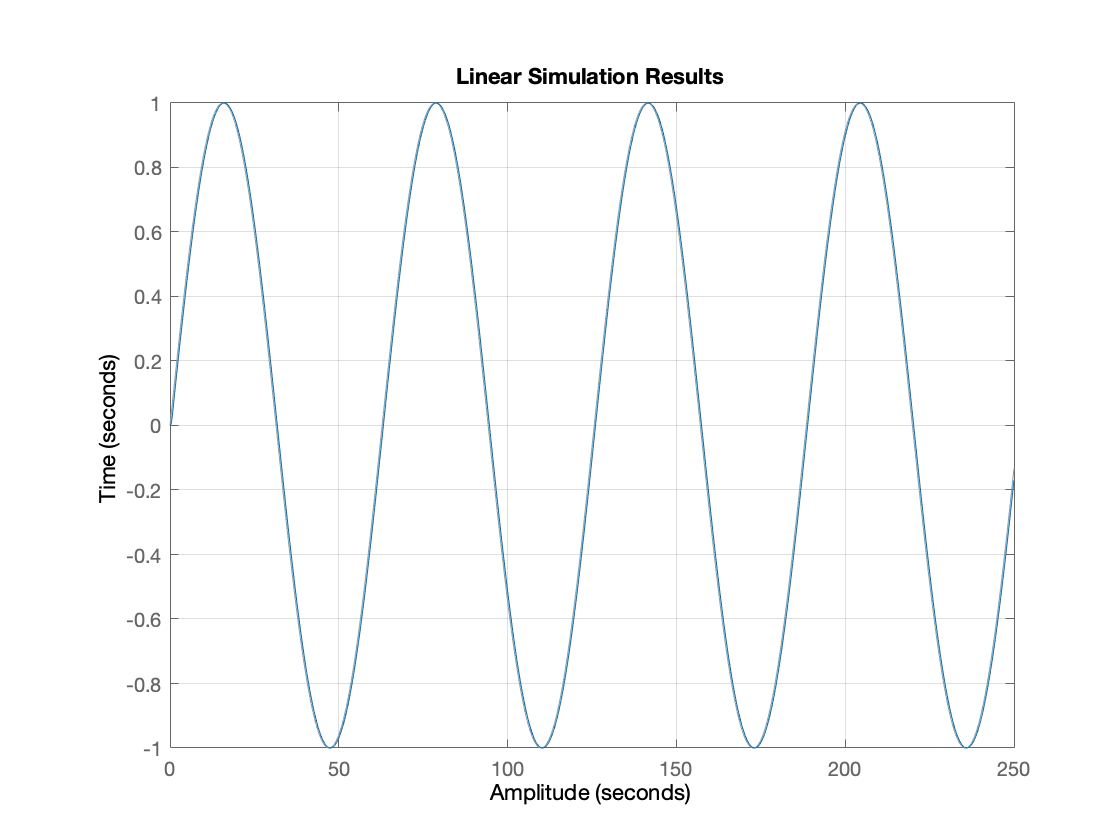

% Define the transfer function of the system
% Please search 'tf' in MATLAB documentation for understanding this function
% tf(Numerator, [denominator])
H_s = tf(16,[1 6 16]);
%define Linear Systems A, B, C, D
A = [0 1; -16 -6];
B = [0; 16];
C = [1 0];
D = 0;
% Define state-space model. 
% Please search 'ss' in MATLAB documentation for understanding this function
% sys = ss(A,B,C,D) creates a state-space model object representing the continuous-time state-space model
sys = ss(A, B, C, D);
% Define initial state
% Ask Wang why is this matrix a 1x2
% The reason why is becasue x is genweight that the matrices are being
% multiplied by
x0 = [0,0];
% Define the input. Here using sinusoidal signal
% **** Please search 'gensig' in MATLAB documentation for learning how to
% genaerate signal. 'gensig' can also used to create square signal.
% u(t) = sin(0.1t)
tau = (2*pi)/(0.1); % period T = 2*pi/0.1
% 0:Ts:Tftool
Ts = 0.01; % time step
Tf = 250; % Duration **** pick a proper dutation for the system in the lab manual
hold on
[u,t] = gensig('sin',tau,Tf,Ts);
% Simulate the system
hold on
lsim(sys,u,t, x0);
grid on;
title('Linear Simulation Results');
xlabel('Amplitude');
ylabel('Time (seconds)');

## 8.2:  SIMULATE SYSTEM WITH EULER METHOD

(b) The procedures are similar to the function 'lab2' defined in the Table 1.

The example shown in Euler.m. The inputs are the initial condition x0 and the step-size h.

Note: 'flops' function has been removed from MATLAB, use tic, toc instead.

(c) 

The value for $T_s$ (the settling time) can be determined using the following equation:


$$T_s =\frac{4\ldotp 6}{\sigma }$$
 

where from the previous lab, sigma was defined as: 3. Therefore, $T_s =\frac{4\ldotp 6}{3}\approx 1\ldotp 5$

Simulation time step for h = 0.01

Euler Simulation Took = 0.132505 ms


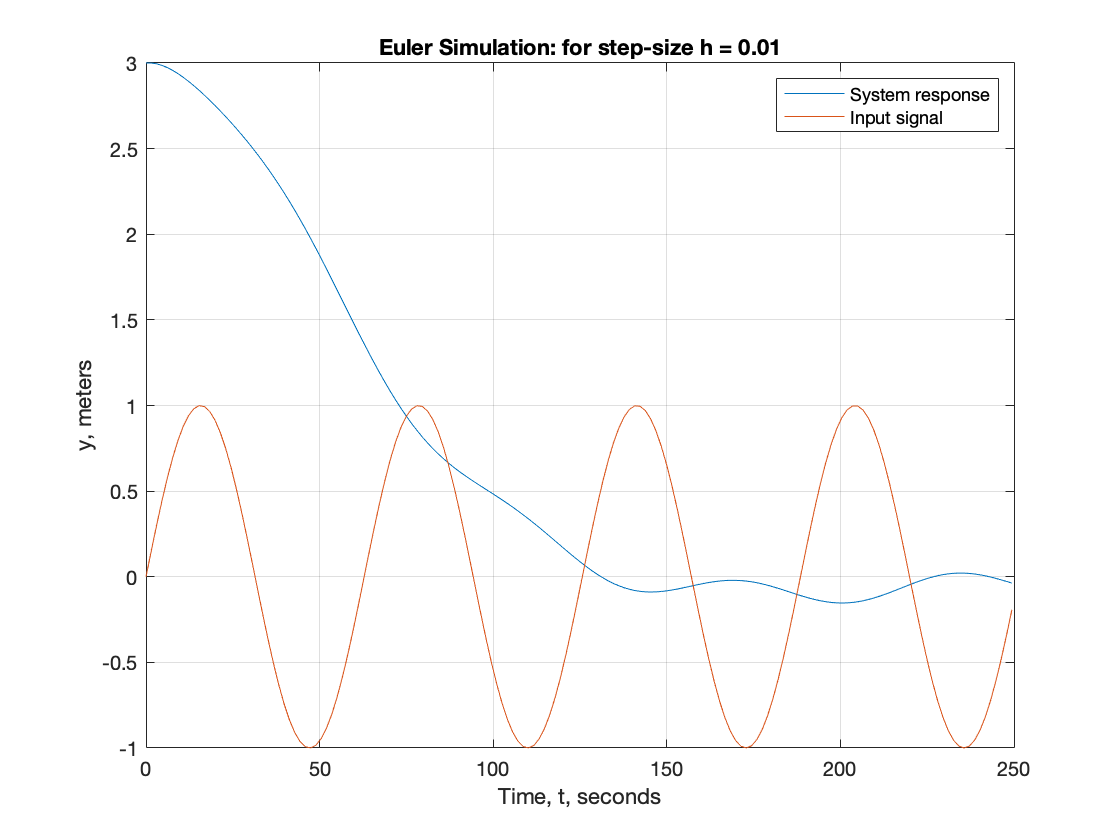

Ts = 1.53; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
% Define initial state
x0 = [3,0];
% Define step-size
h = 0.01;
Euler(t,x0,h,u,1);

Simulation time step for h = 1

This is a poor result because the sampling is done once every 100 times of the time constant.

Euler Simulation Took = 0.161887 ms


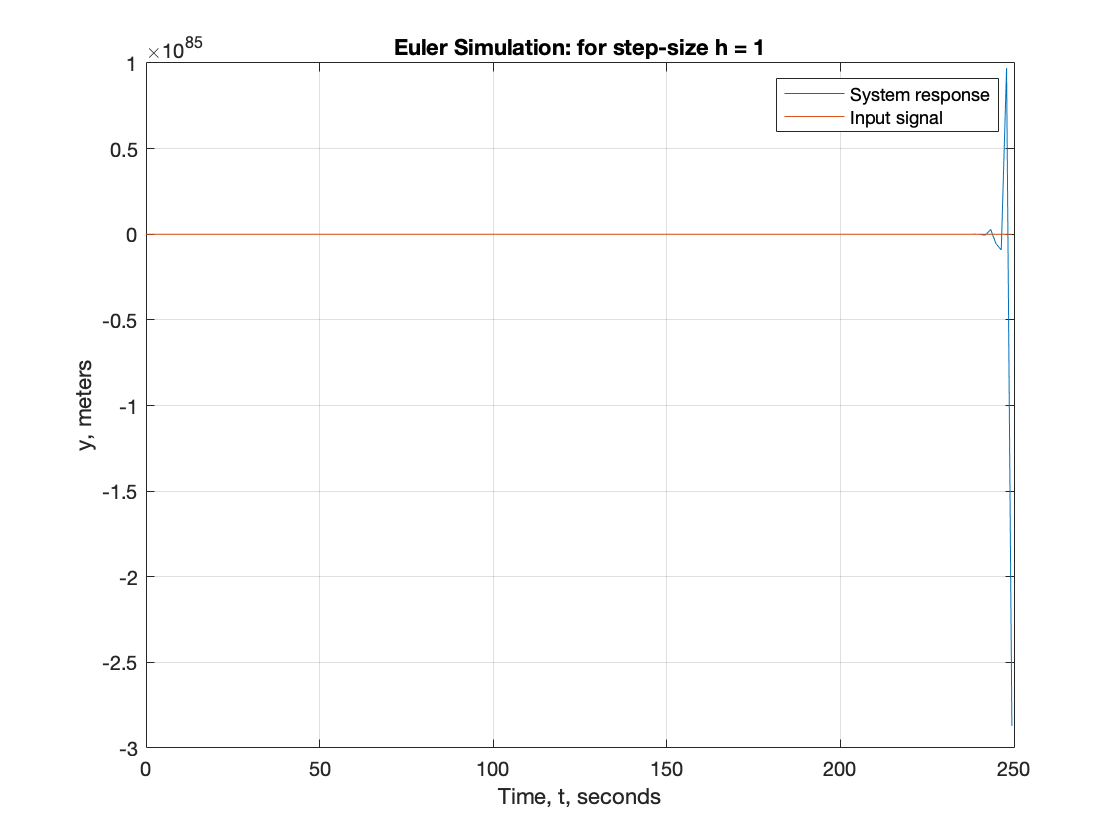

Ts = 1.53; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
h = 1;
Euler(t,x0,h,u,1);

Simulation time step for h = 0.05

This is a horrible simulation because the results are 100 samples for the time constant. Causing this system to be unstable. 

Euler Simulation Took = 0.134571 ms


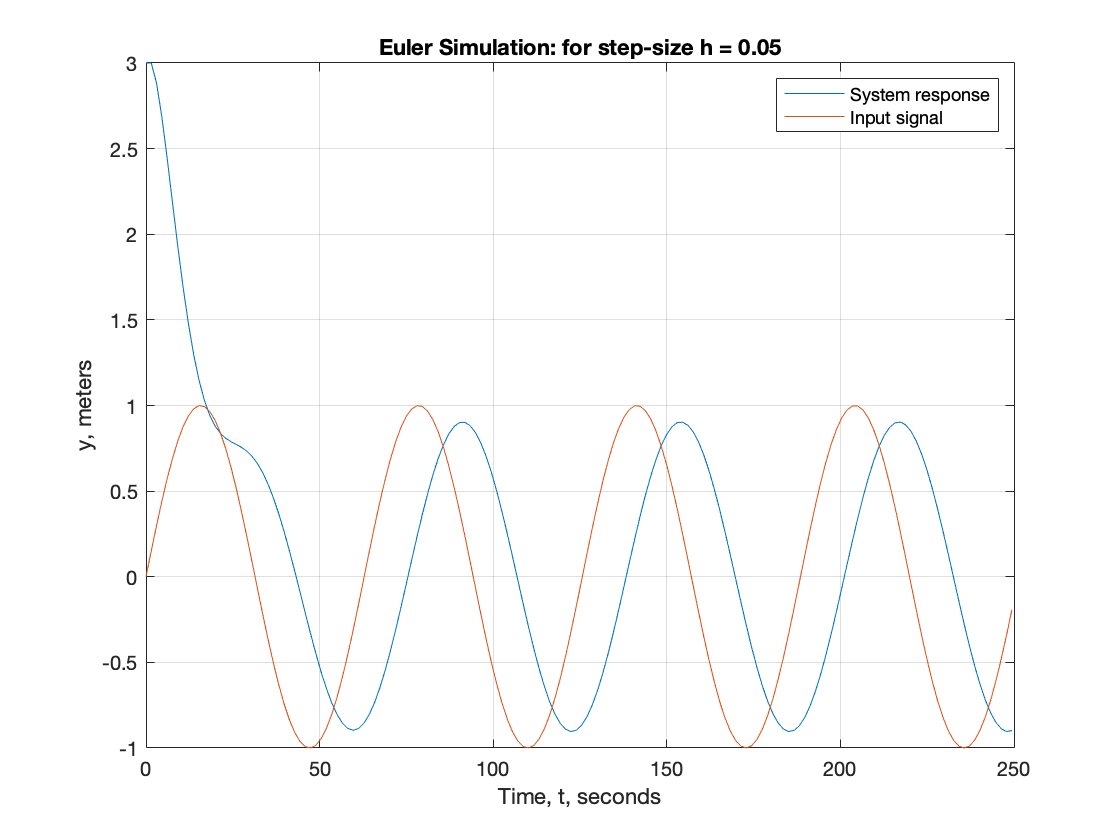

Ts = 1.53; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
h = 0.05;
Euler(t,x0,h,u,1);

Simulation time step for h = 0.1

The accuracy here is a little better because the step size yield 5 samples for every 100 times of the time constant

Euler Simulation Took = 0.124746 ms


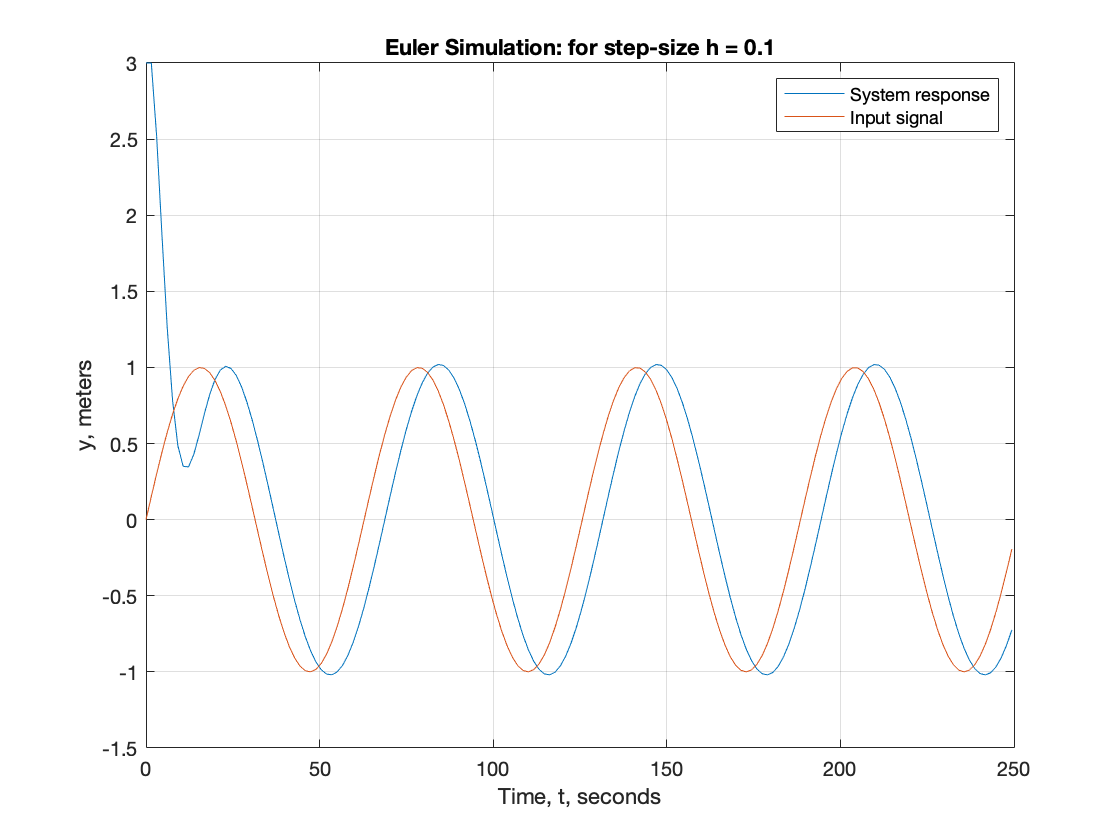

Ts = 1.53; % time step
[u,t] = gensig('sin',tau,Tf,Ts);
h = 0.1;
Euler(t,x0,h,u,1);

c) This step size is in the best fit for the simulation using Euler's approach. This demonstrates the rule of thumb that a step size should be chosen  such that it yields a ten samples of the fastest time constant. I know see why the accuracy of the simulation using Euler's formula is proportional to the rate of T.Doing this requires a lot of computation. And as our systems become more complex, i.e. more parameters., increased poles, i.e. simulation using Euler's method proves less efficient. ode

## 8.3 & 8.4: SIMULATE SYSTEM WITH ODE23

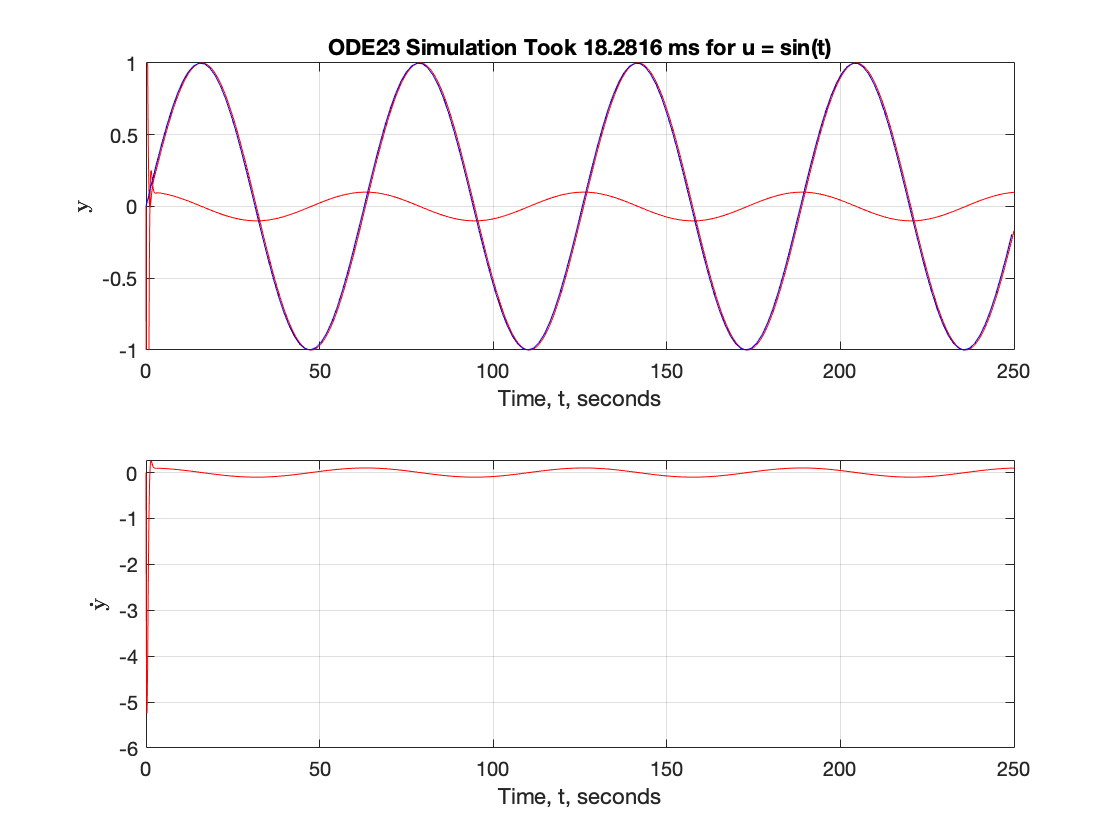

tspan = [0 250]; % Interval of integration
x0 = [3;0]; % Initial condition
% u(t) = sin(t) defined in f_ode23
omg = .1;
tic 
[t_out,y] = ode23(@(t,x) f_ode23(t,x,omg), tspan, x0);
tm = toc; 
tm = tm*1000; 

figure
subplot(211)
% plot y versus t
plot(t_out,y, 'red')
str = sprintf('ODE23 Simulation Took %g ms for u = sin(t)', tm); 
hold on
plot(t,u, 'blue');
title (str)
xlabel('Time, t, seconds');
ylabel('$ \bf y$', 'Interpreter', 'latex');
grid on;
ylim([-1,1]);
subplot(212)
% plot y dot versus t
plot(t_out, y(:,2),'red');
xlabel('Time, t, seconds');
ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
grid on;

C). The computational approach for the Euler formula is a whole order of magnitude faster than the ODE method. The slowest compuational time for the Euler was about 0.16ms. This was when the step size  is  is faster than that of the method for the Euler method. For the Euler method's simulation time to come close to the ODE's I had to reduce the step size to 0.1. Which, as stated in the description  as the good rule of thumb; make the step size one tenth of the fastest time constant. The CPU time required to perform the ode23 simulation was 17ms. 

## 8.5

Choose three diffrent values of $\omega$. Implement (b)&(c) above.

`1. with $\omega_n <<\mathrm{omg}$

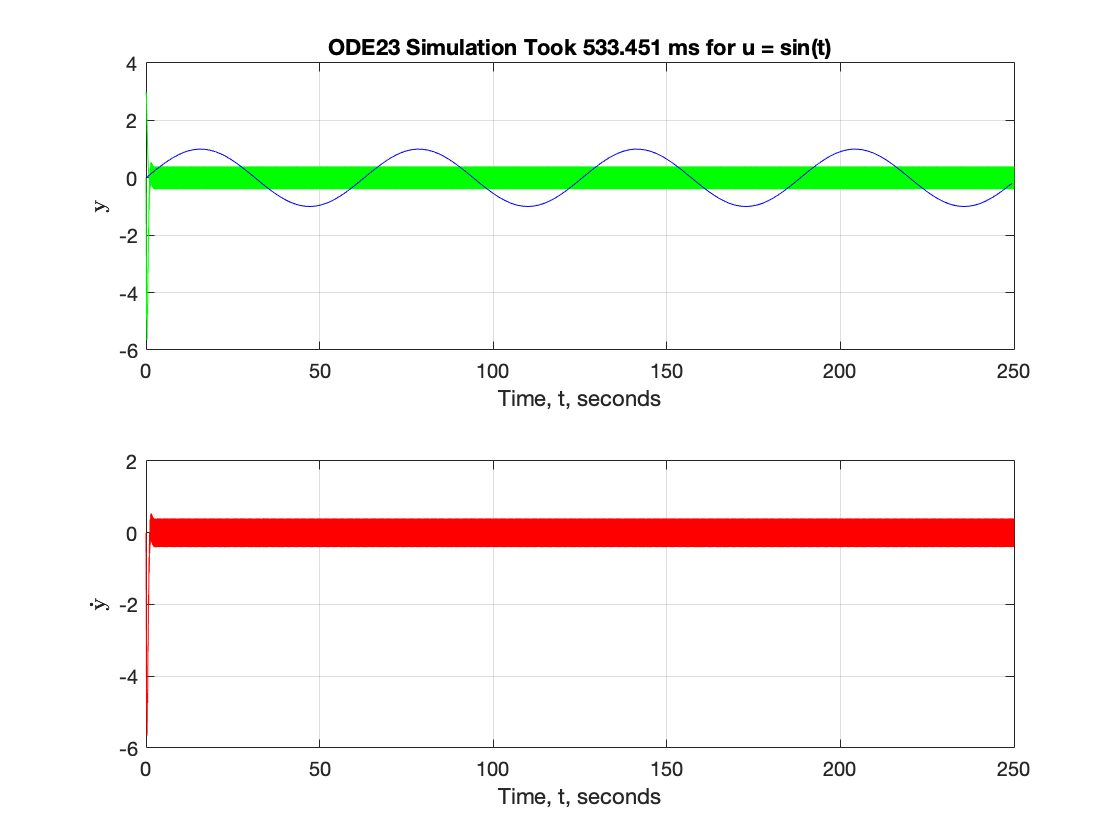

tspan = [0 250]; % Interval of integration
x0 = [3;0]; % Initial condition
% u(t) = sin(t) defined in f_ode23
omg = 40;
tic 
[t_out,y] = ode23(@(t,x) f_ode23(t,x,omg), tspan, x0);
tm = toc; 
tm = tm*1000; 

figure
subplot(211)
% plot y versus t
plot(t_out,y, 'green')
str = sprintf('ODE23 Simulation Took %g ms for u = sin(t)', tm); 
hold on
plot(t,u, 'blue');
title (str)
xlabel('Time, t, seconds');
ylabel('$ \bf y$', 'Interpreter', 'latex');
grid on;
subplot(212)
% plot y dot versus t
plot(t_out, y(:,2),'red');
xlabel('Time, t, seconds');
ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
grid on;

2. When $\omega_n =\mathrm{omg}$

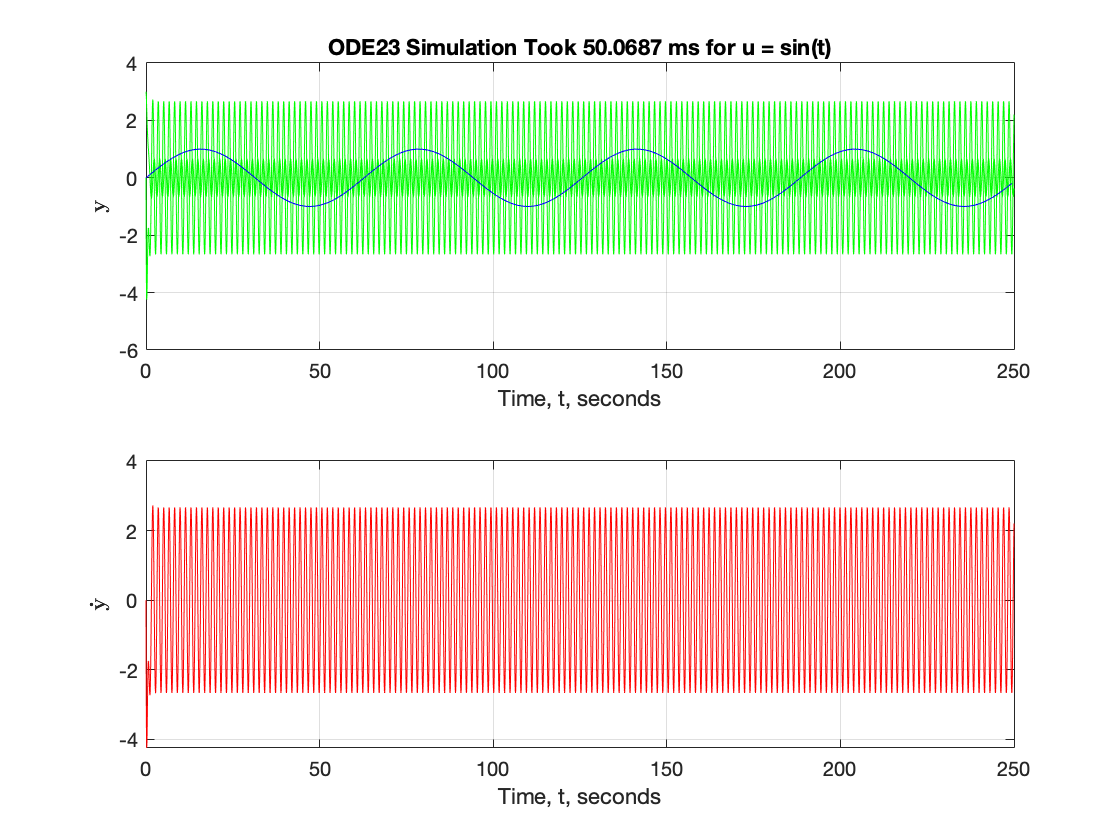

tspan = [0 250]; % Interval of integration
x0 = [3;0]; % Initial condition
% u(t) = sin(t) defined in f_ode23
omg = 4;
tic 
[t_out,y] = ode23(@(t,x) f_ode23(t,x,omg), tspan, x0);
tm = toc; 
tm = tm*1000; 

figure
subplot(211)
% plot y versus t
plot(t_out,y, 'green')
str = sprintf('ODE23 Simulation Took %g ms for u = sin(t)', tm); 
hold on
plot(t,u, 'blue');
title (str)
xlabel('Time, t, seconds');
ylabel('$ \bf y$', 'Interpreter', 'latex');
grid on;
subplot(212)
% plot y dot versus t
plot(t_out, y(:,2),'red');
xlabel('Time, t, seconds');
ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
grid on;

3. when $\omega_n$ >> omg

tspan = [0 250]; % Interval of integration
x0 = [3;0]; % Initial condition
% u(t) = sin(t) defined in f_ode23
omg = .004;
tic 
[t_out,y] = ode23(@(t,x) f_ode23(t,x,omg), tspan, x0);
tm = toc; 
tm = tm*1000; 

figure
subplot(211)
% plot y versus t
plot(t_out,y, 'green')
str = sprintf('ODE23 Simulation Took %g ms for u = sin(t)', tm); 
hold on
plot(t,u, 'blue');
title (str)
xlabel('Time, t, seconds');
ylabel('$ \bf y$', 'Interpreter', 'latex');
grid on;
subplot(212)
% plot y dot versus t
plot(t_out, y(:,2),'red');
xlabel('Time, t, seconds');
ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
grid on;

Discuss and compare the amplitude and phase shift of the output relative to the input.

How do the steady state values compare with those predicted by frequency response (try using the ‘Bode’ function)?  

5) 

The steady state values compared with those predicted by the frequency response using the bode plot are in line. the Euler step 0.1 and is shown to be good because it is in line with the phase shift of the system. Moreover, the same magnitdue of 1 was simulated in the Euler and the ode23 method. Thus, bode plots are a much simpler way to simulate and understand the frequency response of a system. It requires much less compuation and less code. This reduces the error rate. The computation is exact and only takes 10ms. The Euler formula is fast, however, the need to pick an appriopriate step size can qucikly become a hassle when dealing with multiple parameters. 

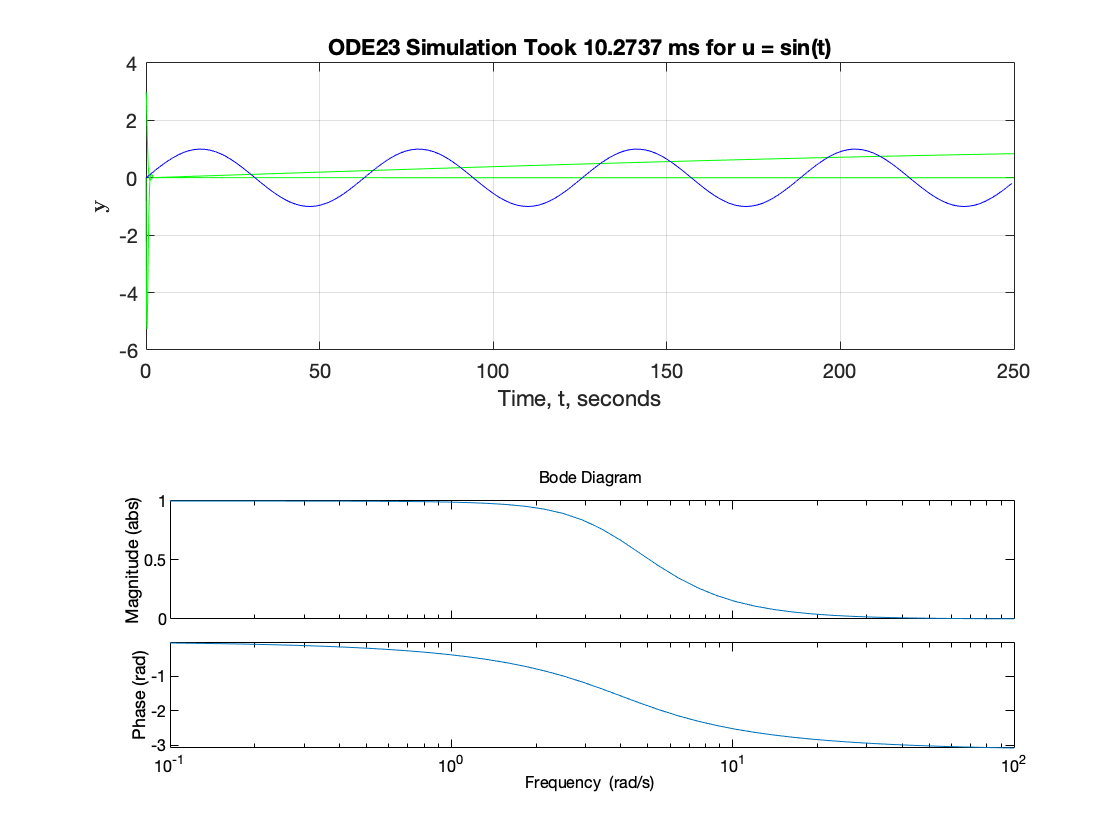

% bode(H); find the magnitude and phase in frequecy related to the input.
opts = bodeoptions;
opts.MagUnits = 'abs';
opts.PhaseUnits = 'rad';
h = bodeplot(H_s,opts);